First, load an image and convert it to a binary format. We also make the image square, and normalize the pixel range to [0, 1]. This matrix, `X`, is the true signal.

rgb_img = imread('oprah.jpg');
grey_img = rgb2gray(rgb_img);

% crop the image to square 
offset = ceil((size(grey_img, 2) - size(grey_img, 1)) / 2)  ;
lb = offset + 1;
ub = size(grey_img, 2) - offset;

% convert the image to a normalized greyscale image
% note that the original image is an RGB imagee
X = im2double(grey_img(:, lb:ub));
size(X)

ans =    890   890


Now we add noise to the true signal, with a known noise factor $\alpha$. The factor $\alpha$ is the *amount* of noise we add. We use this factor to scale a matrix, `Z`, whose entries are drawn from a standard normal distribution ($\mu = 0, \sigma=1$). A higher $\alpha$ results in greater distortion to the original image. The matrix `Z` has the same dimensions as the original image.

    
$$\mathbf{Y} = \mathbf{X} + \alpha \mathbf{Z}$$


The resulting matrix, `Y`, is what we observe. That is, we are given data that is noisy, but that has a true signal "buried" inside of it. We hope to be able to extract this true signal from the messy data `Y`.

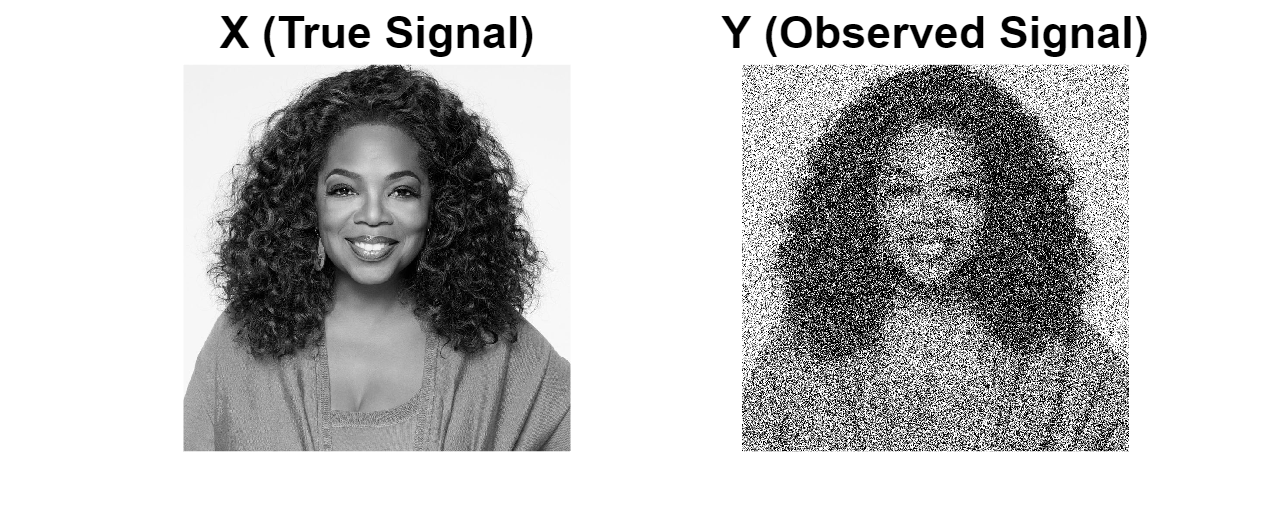

close all;
alpha = 0.5;
Z = randn(size(X));
scaled_Z = alpha * Z;
Y = X + scaled_Z;

% plot the two images side by side
subplot(1, 2, 1);
imshow(X);
title('X (True Signal)', 'FontSize', 30);

subplot(1, 2, 2);
imshow(Y);
title('Y (Observed Signal)', 'FontSize', 30);
fig = gcf; % resize the figure 
fig.Position(:)=[1500, 600, 1500, 600];

Given only `Y` and knowledge about $\alpha$, can we recover the true signal? The answer is "partially," and the approach is based on the SVD of a data matrix:

    
$$\mathbf{A} = \mathbf{U} \mathbf{\Sigma} \mathbf{V}^{\text{T}}
$$


We can take either `X` or `Y` to be the data matrix. In practice we are only given `Y.` Either way, we can define the truncated SVD of the data matrix up to some value, `r`:

    
$$\mathbf{\hat{A}} = \sum_{i=1}^r \sigma_i u_i v_i^\text{T}}$$


This summation of outer products gets us closer and closer to the data matrix as we increase the number of singular values and vectors included (as `r` becomes larger). Basically, we get a better and better approximation as we include more singular value/vector products.

**Note 1**, to illustrate this, we will  use the image `X` because it is easier to see what's going on. But in real life *we do not have *`X`. 

**Note 2, **There are 890 singular values for this data. We are looking only at the first 10 and increasing by 2 each time. This shows that most of the information is included in the most dominant signular value/vector products, i.e., that the true signal has low rank. By the 30 top singular values we have an image that is a reasonably clear approximate of the original!

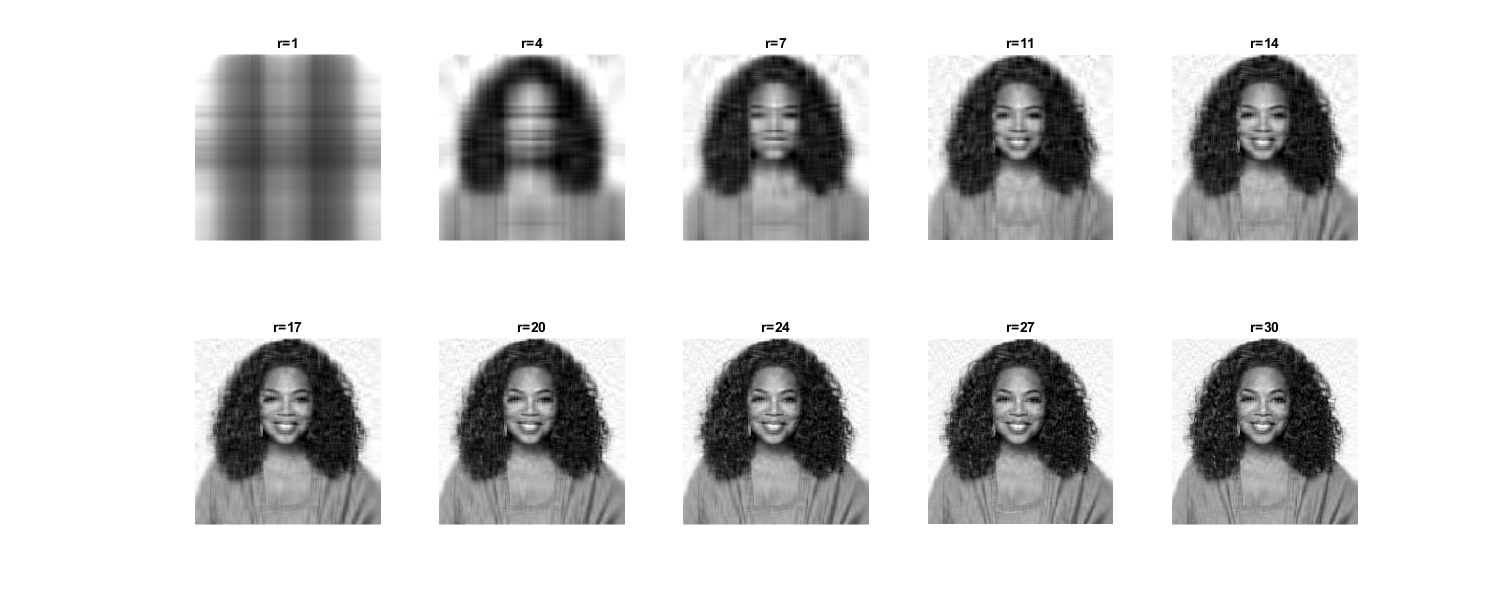

close all;

% take the SVD of the image
[U, S, V] = svd(X);

singular_value_indices = cast(linspace(1, 30, 10), 'uint8');

for i=1:10
    % get the number of singular values to include in the summation above
    r = singular_value_indices(i);
    
    % reconstruct the original data matrix using only the top `r` 
    % singular values and singular vectors
    X_approx = U(:,1:r)*S(1:r,1:r)*V(:,1:r)';
    subplot(2, 5, i);
    imshow(X_approx);
    title(['r=', num2str(r)])
end

fig = gcf; % resize the figure 
fig.Position(:)= [1500, 600, 1500, 600];

For the above, we just took "snapshots" of the approximation for the values in `singular_value_indices`. In the right plot each red line represents where we took an `r` snapshot, i.e, we treat that number as a threshold for thew singular values that we inlcude in the truncated SVD. We only look at the top few singular values, but there are hundreds (see the left plot)! An important implication of this is that the original image is low rank.

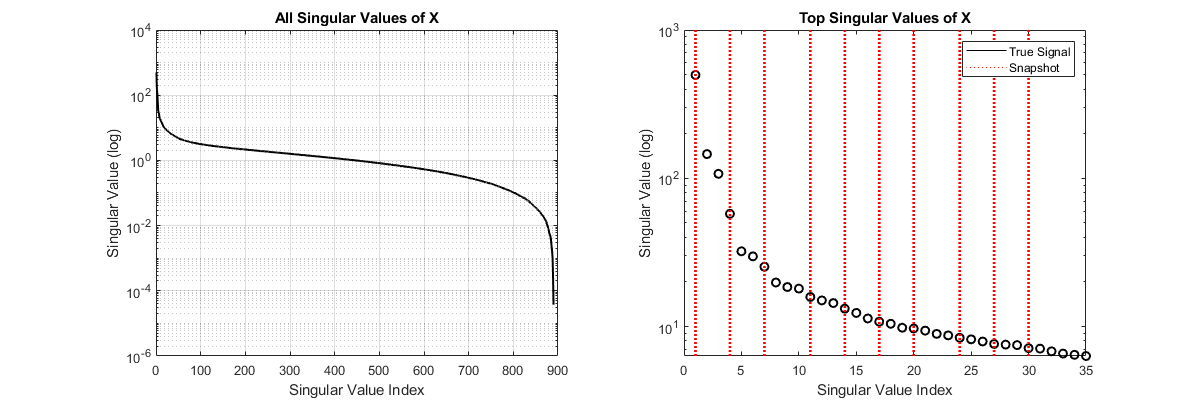

close all; 

S = diag(S);

subplot(1, 2, 1);
semilogy(S,'k','LineWidth',1.5);
title("All Singular Values of X");
ylabel('Singular Value (log)');
xlabel('Singular Value Index');
grid on;

subplot(1, 2, 2);
semilogy(S(1:35),'ok','LineWidth',1.5);
title("Top Singular Values of X");
ylabel('Singular Value (log)');
xlabel('Singular Value Index');
y = ylim; % current y-axis limits
hold on;

for i=1:10
    r = singular_value_indices(i);
    plot([r r],[y(1) y(2)], ':r','LineWidth',2)
end

h = zeros(2, 1);
h(1) = plot(NaN,NaN,'k');
h(2) = plot(NaN,NaN,':r');
legend(h, 'True Signal','Snapshot');

fig = gcf; % resize the figure 
fig.Position(:)= [1200, 400, 1200, 400];

Let's compare the singular value spectra of the two images, the original and the observed. The top row is the descending singular values of each matrix. The second row is just the top 50 singular values of each. Think of the second row as a "zoomed in" plot of what's going on near the y-axis in the first row.

 Check out how the noisy matrix, `Y` is dominated by a smaller number of singular values than the original! We can exploit this fact in the next section.

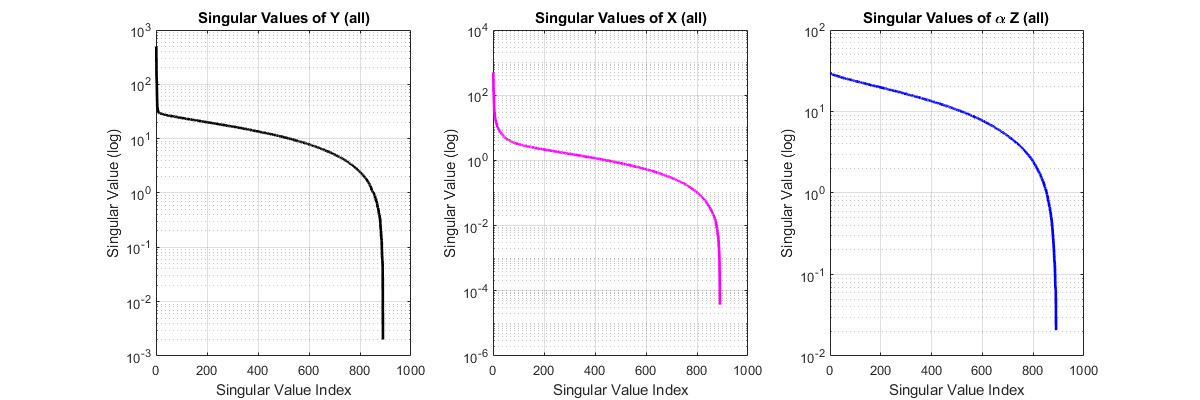

close all;

% take the SVD of both images
[ux, sx, vx] = svd(X);
[uy, sy, vy] = svd(Y);
[uz, sz, vz] = svd(scaled_Z);

sx_vec = diag(sx);
sy_vec = diag(sy);
sz_vec = diag(sz);

subplot(1, 3, 1);
semilogy(sy_vec,'-k','LineWidth',2);
title('Singular Values of Y (all)');
ylabel('Singular Value (log)');
xlabel('Singular Value Index');
grid on;

subplot(1, 3, 2);
semilogy(sx_vec,'-m','LineWidth',2);
hold on;
grid on;
title('Singular Values of X (all)');
ylabel('Singular Value (log)');
xlabel('Singular Value Index');

subplot(1, 3, 3);
semilogy(sz_vec,'-b','LineWidth',2);
title('Singular Values of \alpha Z (all)');
ylabel('Singular Value (log)');
xlabel('Singular Value Index');
grid on;

fig = gcf; % resize the figure 
fig.Position(:)= [1200, 400, 1200, 400];

We can plot the spectra ofthe noise matrix, $\alpha \mathbf{Z}$and the observed signal `Y`, here we only look at the top 50 singular values.

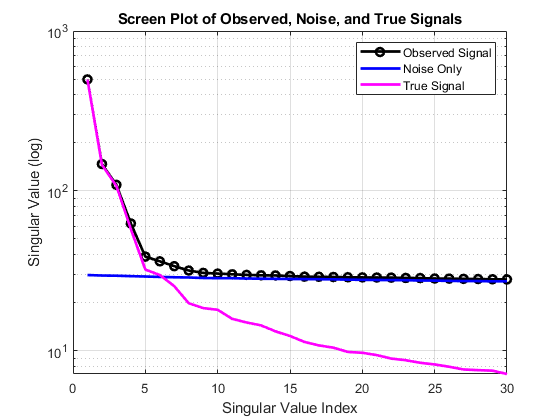

close all;

semilogy(sy_vec(1:30),'-ok','LineWidth',2);
title('Screen Plot of Observed, Noise, and True Signals');
ylabel('Singular Value (log)');
xlabel('Singular Value Index');
grid on;
hold on;
semilogy(sz_vec(1:30),'-b','LineWidth',2);
semilogy(sx_vec(1:30),'-m','LineWidth',2);
legend('Observed Signal', 'Noise Only', 'True Signal');

As before, we can use the truncated SVD to take snapshots. This time we look at the observed matrix `Y`. Note that it is no longer clear where we stop adding outer products. Does the approximation keep getting better after `r=14`?

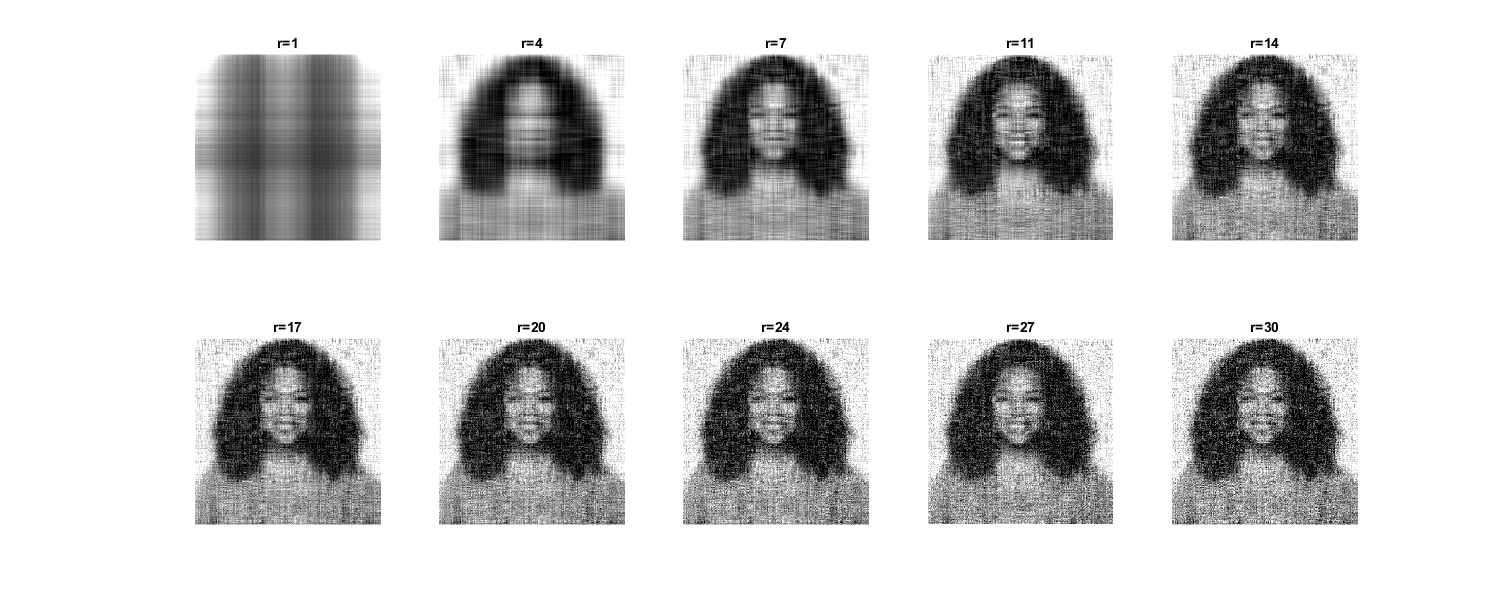

close all;

% take the SVD of the image
[U, S, V] = svd(Y);

singular_value_indices = cast(linspace(1, 30, 10), 'uint8');

for i=1:10
    % get the number of singular values to include in the summation above
    r = singular_value_indices(i);
    
    % reconstruct the original data matrix using only the top `r` 
    % singular values and singular vectors
    Y_approx = U(:,1:r)*S(1:r,1:r)*V(:,1:r)';
    subplot(2, 5, i);
    imshow(Y_approx);
    title(['r=', num2str(r)])
end

fig = gcf; % resize the figure 
fig.Position(:)= [1500, 600, 1500, 600];

Since we know $\alpha$ we can compute the *best* place to stop taking outer products into consideration using the following formula:

    
$$\tau = \frac{4}{\sqrt{3}} \left ( \sqrt{n}  \right ) \alpha$$


The value of tau ($\tau$) will tell us when to stop including singular value/vector products. 

N = size(Y,1);
cutoff = (4/sqrt(3))*sqrt(N)*alpha; % Hard threshold
tau = find(diag(S)>cutoff, 1, 'last'); 
tau

tau = 6

The plot on the left shows where that occurs in the spectra and the plot on the right shows what the optimal reconstruction of the true signal looks like. Note, we might believe that we can do better, i.e., get a better reconstruction. It is important to remember that this is theoretically guaranteed to be a low-error reconstruction if we know the noise factor $\alpha$.  

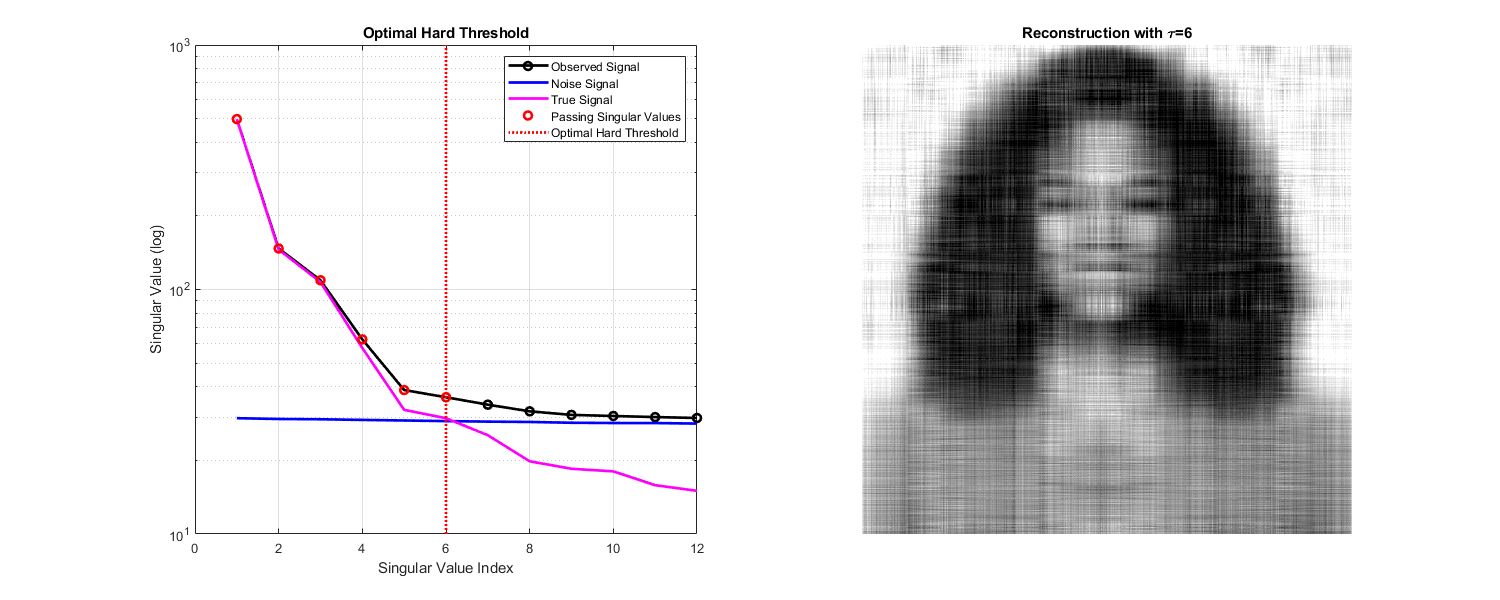

close all;

N_vals = 12;

subplot(1, 2, 1);
semilogy(sy_vec(1:N_vals),'-ok','LineWidth',2);
title('Optimal Hard Threshold');
ylabel('Singular Value (log)');
xlabel('Singular Value Index');
grid on;
hold on;
semilogy(sz_vec(1:N_vals),'-b','LineWidth',2);
semilogy(sx_vec(1:N_vals),'-m','LineWidth',2);
semilogy(sy_vec(1:tau),'or','LineWidth',2);

y = ylim; % current y-axis limits
plot([tau tau],[y(1) y(2)], ':r','LineWidth',2)

legend("Observed Signal", "Noise Signal", "True Signal", "Passing Singular Values", "Optimal Hard Threshold");

subplot(1, 2, 2);
Y_approx = uy(:,1:tau)*sy(1:tau,1:tau)*vy(:,1:tau)';
imshow(Y_approx);
title(['Reconstruction with \tau=', num2str(tau)])

fig = gcf; % resize the figure 
fig.Position(:)= [1500, 600, 1500, 600];

But what if we don't know $\alpha$? We can still make an approximation using the following hueristic:

    
$$\hat{\tau} \approx 2.858 \times \text{median}(\mathbf{S})$$


Where $\mathbf{S}$ is the vector of singular values such that $\mathbf{S} = [\sigma_1, \sigma_2, \dots, \sigma_n] $. 

cutoff = 2.858 * median(sy_vec);
tau_approx = find(diag(S)>cutoff, 1, 'last'); 
tau_approx

tau_approx = 6